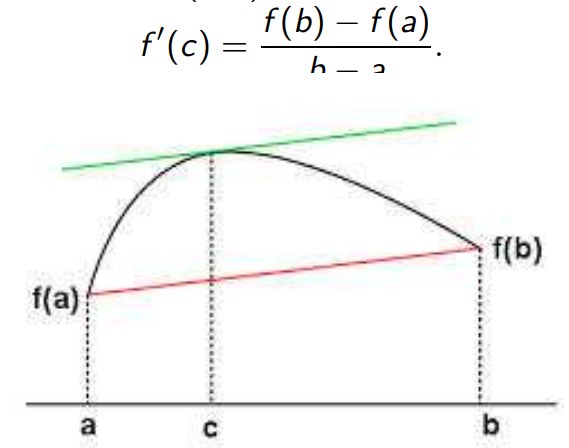

## 拉格朗日中值定理

### 第一步(求xi)

利用求解xi

#### diff(f(x))--求一阶导

x为变量，对x求导

#### fzero(f,[x1,x2])--求函数根

解出非线性函数在[x1,x2]范围内的根

#### inline('f(x)')--变量转字符型

### 第二步(求b)

将第一步所得答案带入，解出b

其中g=f(c) 

#### solve(f(x)==0,x)--解方程

x为变量

解出等式中x的值

#### plot([x1,x2],[y1,y2])--画直线

画一条经过点(x1,y1),(x2,y2)的直线

syms x b
diff(1/x^4)

$$ans = -\frac{4}{x^{5}}$$

c=fzero('-4/x^5-1/16+1',[1,2])

c = 1.3367


diff(1/x^4)

$$ans = -\frac{4}{x^{5}}$$

f=inline('-4/x^5-1/16+1');%1/16为f(2),1为f(1)
c=fzero(f,[1,2])

c = 1.3367


ans=solve(0.3132==-0.9375*1.3367+b,b)

$$ans = \frac{250617}{160000}$$

double(ans)

ans = 1.5664

g=-0.9375*x+1.5664

$$g = \frac{979}{625}-\frac{15\,x}{16}$$

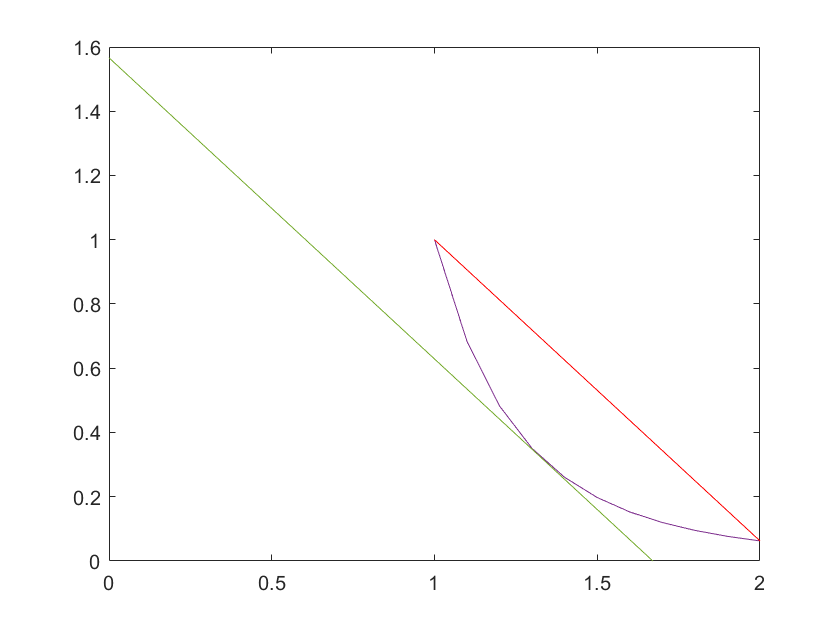

u=1:0.1:2;


z=1./u.^4;%原函数
plot(u,z);
hold on;
plot([0,1.6708],[1.5664,0])%g
plot([1,2],[1,1/16],'r')%画(1,f(1)),(2,f[2])的直线

## 解方程

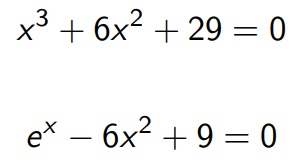

### 1.fzero函数

f='x^2+2*x+4'

#### fzero(f,[a,b])--返回[a,b]范围内的根

#### fzero(f,x0)--返回接近x0的根

syms x
fzero('x^3+6*x^2+29',[-10,10])

ans = -6.6548

fzero('exp(x)-6*x^2+9',0)

ans = -1.2442

### 2.solve（f==0)

f='x^2+2*x+4'

r=solve(f);

solve(x^3+6*x^2+29==0)

$$ans = \left(\begin{array}{c} \mathrm{root}\left(z^{3}+6\,z^{2}+29,z,1\right)\\ \mathrm{root}\left(z^{3}+6\,z^{2}+29,z,2\right)\\ \mathrm{root}\left(z^{3}+6\,z^{2}+29,z,3\right) \end{array}\right)$$

solve(exp(x)-6*x^2+9==0)

$$ans = -1.2441979967238808493912781618914$$

### 3.roots([an,an-1,...a1,a0])

c=[an,an-1,...a1,a0]

r=roots(c );

an..a0为其系数

roots([1,6,0,29])

ans =   -6.6548 + 0.0000i
   0.3274 + 2.0617i
   0.3274 - 2.0617i


例1.

clf;
syms x
diff(x^3-2*x+1)

$$ans = 3\,x^{2}-2$$

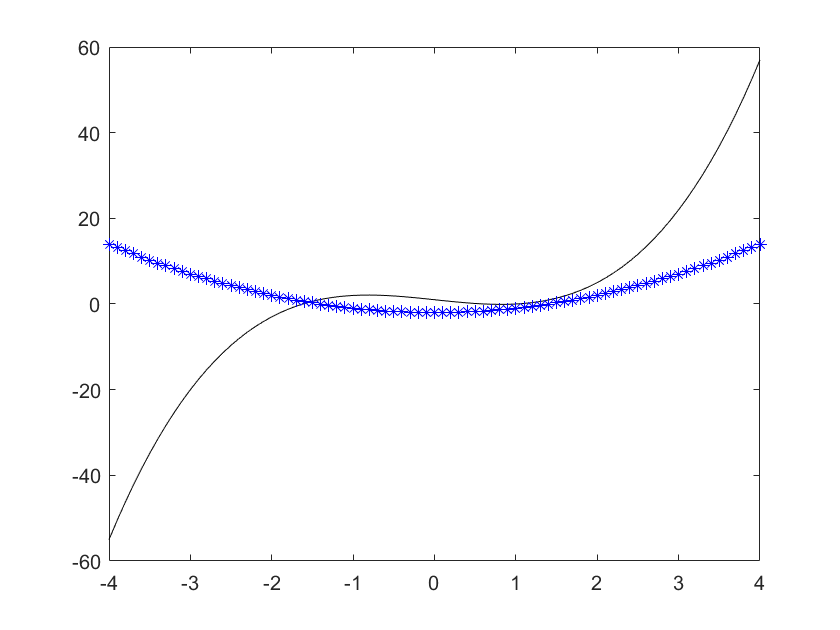

x=-4:0.1:4;
y1=x.^3-2*x+1;
y2=x.^2-2;
plot(x,y1,'k-',x,y2,'b*')

c=roots([3,0,-2])%3*x^2-2

c =     0.8165
   -0.8165


## 练习1.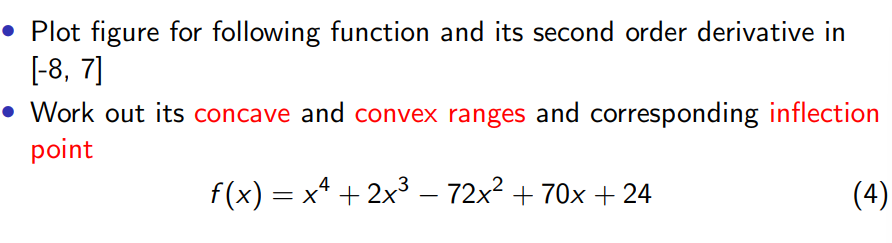

画出原函数和二阶导函数，计算出其凹凸范围(二阶导零点)及相应的拐点

clf;
syms x
diff(x^4+2*x^3-72*x^2+70*x+24,2)

$$ans = 12\,x^{2}+12\,x-144$$

x=-8:0.1:7

x =    -8.0000   -7.9000   -7.8000   -7.7000   -7.6000   -7.5000   -7.4000   -7.3000   -7.2000   -7.1000   -7.0000   -6.9000   -6.8000   -6.7000   -6.6000   -6.5000   -6.4000   -6.3000   -6.2000   -6.1000   -6.0000   -5.9000   -5.8000   -5.7000   -5.6000   -5.5000   -5.4000   -5.3000   -5.2000   -5.1000   -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000


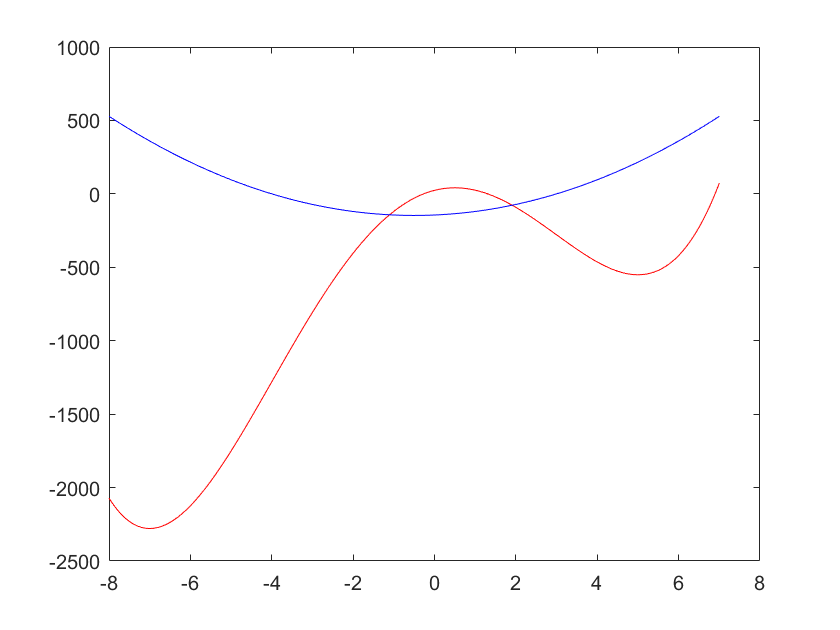

y0=x.^4+2*x.^3-72*x.^2+70*x+24;
dy0=12*x.^2+12*x-144;
plot(x,y0,'r',x,dy0,'b')

roots([12,12,0,-144])

ans =   -1.5000 + 1.9365i
  -1.5000 - 1.9365i
   2.0000 + 0.0000i


练习2.

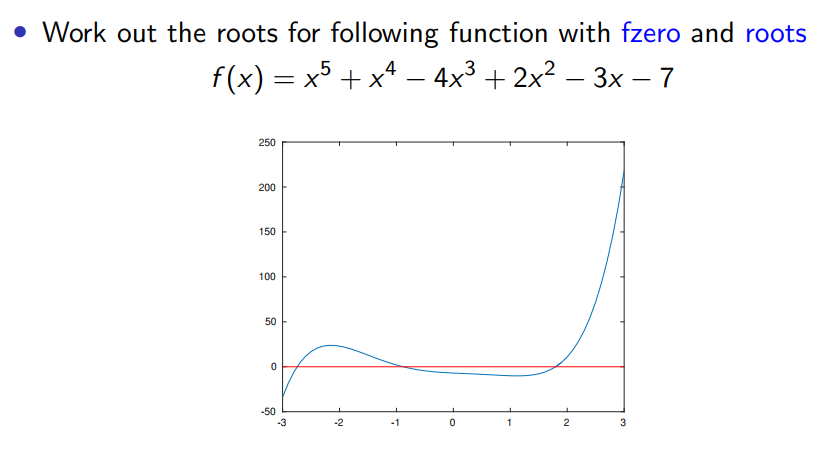

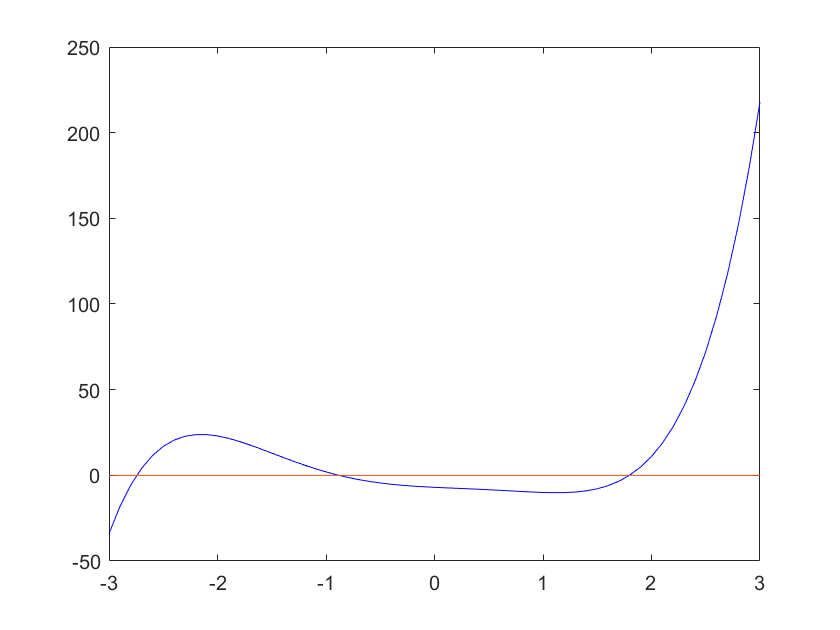

clf;
x=-3:0.1:3;
y=x.^5+x.^4-4*x.^3+2*x.^2-3*x-7;
plot(x,y,'b')
hold on
plot([-3,3],[0,0])


%用fzero
fzero('x^5+x^4-4*x^3+2*x^2-3*x-7',-3)

ans = -2.7446

fzero('x^5+x^4-4*x^3+2*x^2-3*x-7',-1)

ans = -0.8809

fzero('x^5+x^4-4*x^3+2*x^2-3*x-7',2)

ans = 1.7965


fzero('x^5+x^4-4*x^3+2*x^2-3*x-7',[-3,3])

ans = -2.7446



%用solve
syms x
solve(x^5+x^4-4*x^3+2*x^2-3*x-7==0)

$$ans = \begin{array}{l} \left(\begin{array}{c} \mathrm{root}\left(\sigma_{1},z,1\right)\\ \mathrm{root}\left(\sigma_{1},z,2\right)\\ \mathrm{root}\left(\sigma_{1},z,3\right)\\ \mathrm{root}\left(\sigma_{1},z,4\right)\\ \mathrm{root}\left(\sigma_{1},z,5\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z^{5}+z^{4}-4\,z^{3}+2\,z^{2}-3\,z-7 \end{array}$$


%用roots
roots([1,1,-4,2,-3,-7])

ans =   -2.7446 + 0.0000i
   1.7965 + 0.0000i
   0.4145 + 1.2000i
   0.4145 - 1.2000i
  -0.8809 + 0.0000i
